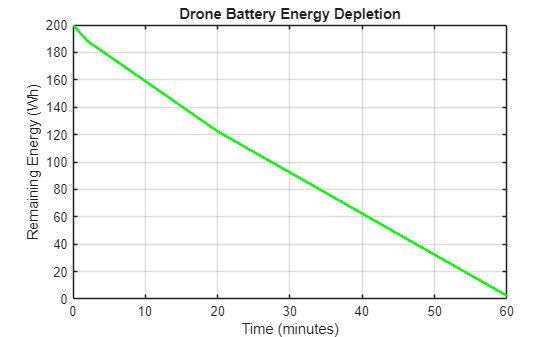

% Author: Christopher Bourjaili
% Module 2
% Project 16
% Title: Drone Battery and Flight Time
%
% Summary of Code:
% - Simulates drone battery energy depletion over time.
% - Uses different power consumption rates for ascent, cruise, and hover.
% - Tracks remaining battery energy each second.
% - Determines total flight time until battery depletion.
% - Creates a plot of battery energy vs time.
% - Shows how flight mode affects endurance.
%
% What I Learned:
% This project demonstrated how MATLAB can model battery usage in an
% aerospace or robotics system using loops, conditionals, and arrays.
% I learned that flight endurance depends strongly on operating mode,
% since higher-power tasks like ascent drain energy faster than hover
% or cruise. I also practiced simulating resource depletion and using
% graphs to visualize remaining battery capacity over time.

clc
clear
close all

battery_capacity = 200;     
dt = 1;                     
t_max = 3600;               

t = 0:dt:t_max;
n = length(t);

P_ascent = 350;
P_cruise = 220;
P_hover  = 180;

energy = zeros(1,n);
power = zeros(1,n);

energy(1) = battery_capacity;

for i = 2:n
    
    if t(i) <= 120
        power(i) = P_ascent;
        
    elseif t(i) <= 1200
        power(i) = P_cruise;
        
    else
        power(i) = P_hover;
    end
    
    energy(i) = energy(i-1) - power(i)*dt/3600;
    
    if energy(i) <= 0
        energy(i) = 0;
        power(i:end) = 0;
        end_time = t(i);
        break
    end
end

if energy(end) > 0
    end_time = t_max;
end

figure
plot(t/60, energy,'g','LineWidth',2)
grid on
xlabel('Time (minutes)')
ylabel('Remaining Energy (Wh)')
title('Drone Battery Energy Depletion')


fprintf('Total Achievable Flight Time = %.2f minutes\n', end_time/60);

Total Achievable Flight Time = 60.00 minutes



disp('Interpretation:')

Interpretation:


disp('1. Ascent consumes the most power and drains battery fastest.')

1. Ascent consumes the most power and drains battery fastest.


disp('2. Cruise uses moderate power for efficient travel.')

2. Cruise uses moderate power for efficient travel.


disp('3. Hover uses less power, increasing endurance.')

3. Hover uses less power, increasing endurance.


disp('4. Flight mode selection strongly affects total mission time.')

4. Flight mode selection strongly affects total mission time.
